clear;
load BFCS_E1E2E3.mat
e1=E1;
e2=E2;
e3=E3;
syms t;
H1(t) = w1(t);
H2(t) = w2(t);
H3(t) = w3(t);
H = double(H);

max_x = max([H/I1, H/I2, H/I3]);
LBC = max_x;
LAD = LBC/2; 
LAG = LAD/2;      
max_x = max_x+1;

%  The T-handle's orientation varies over time according to the evolution
%  of the principal corotational basis {e1,e2,e3}.  Solve for how
%  {e1,e2,e3} vary over time.  Also, keep track of points on the T-handle
%  that are needed to animate its motion:
dt = tsim(2,1)-tsim(1,1);

xA = zeros(length(tsim),1);
yA = zeros(length(tsim),1);
zA = zeros(length(tsim),1);
xB = zeros(length(tsim),1);
yB = zeros(length(tsim),1);
zB = zeros(length(tsim),1);
xC = zeros(length(tsim),1);
yC = zeros(length(tsim),1);
zC = zeros(length(tsim),1);
xD = zeros(length(tsim),1);
yD = zeros(length(tsim),1);
zD = zeros(length(tsim),1);
H0 = [-2*max_x,0,0];
xH1 = zeros(length(tsim),1);
yH1 = zeros(length(tsim),1);
zH1 = zeros(length(tsim),1);

for k = 1:length(tsim)
    xA(k,1) = -LAG*e2(1,k);                        
    yA(k,1) = -LAG*e2(2,k);                                                 
    zA(k,1) = -LAG*e2(3,k);                        
    xB(k,1) = xA(k) + LBC/2*e1(1,k);           
    yB(k,1) = yA(k) + LBC/2*e1(2,k);                                           
    zB(k,1) = zA(k) + LBC/2*e1(3,k);              
    xC(k,1) = xA(k) - LBC/2*e1(1,k);            
    yC(k,1) = yA(k) - LBC/2*e1(2,k);                                          
    zC(k,1) = zA(k) - LBC/2*e1(3,k);               
    xD(k,1) = xA(k) + LAD*e2(1,k);                  
    yD(k,1) = yA(k) + LAD*e2(2,k);                                                
    zD(k,1) = zA(k) + LAD*e2(3,k);               
    xH1(k,1) = H0(1)+double(H3(tsim(k,1)));
    yH1(k,1) = H0(2)+double(H1(tsim(k,1)));
    zH1(k,1) = H0(3)+double(H2(tsim(k,1)));
end
save temp.mat;

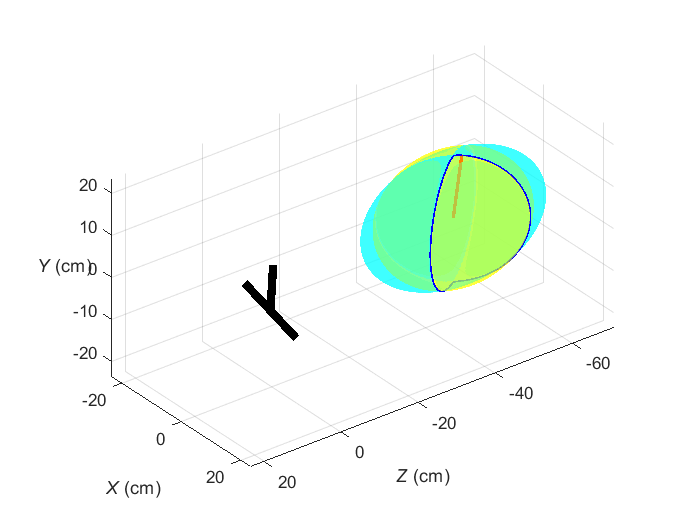

load temp.mat
%  Set up the figure window:
[x1, y1, z1] = ellipsoid(0,0,0,double(H/I1),double(H/I2),double(H/I3),100);
[x2, y2, z2] = ellipsoid(0,0,0,double(sqrt(2*K/I1)),double(sqrt(2*K/I2)),double(sqrt(2*K/I3)),100);
figure
set(gcf, 'color', 'w')
plot3(0, 0, 0);
hold on;
H_ellipsoid = surfl(z1+H0(1), x1+H0(2), y1+H0(3)); 
set(H_ellipsoid, 'FaceAlpha', 0.5, 'FaceColor', 'c', 'EdgeColor', 'none');
T_ellipsoid = surfl(z2+H0(1), x2+H0(2), y2+H0(3)); 
set(T_ellipsoid, 'FaceAlpha', 0.5,  'FaceColor', 'y', 'EdgeColor', 'none');
hold off;
xlabel('\itZ\rm (cm)')
set(gca, 'xdir', 'reverse')
ylabel('\itX\rm (cm)')
set(gca, 'ydir', 'reverse')
zlabel('\itY\rm (cm)', 'rotation', 0)
axis equal
xlim([-3*max_x, max_x]);
ylim([-max_x, max_x]);
zlim([-max_x, max_x]);
grid on

%  Draw the T-handle:

AD = line('xdata', [xA(1), xD(1)], 'ydata', [yA(1), yD(1)], 'zdata', [zA(1), zD(1)], 'color', 'k', 'linewidth', 5);
BC = line('xdata', [xB(1), xC(1)], 'ydata', [yB(1), yC(1)], 'zdata', [zB(1), zC(1)], 'color', 'k', 'linewidth', 5);
H0H1 = line('xdata', [H0(1), xH1(1)], 'ydata', [H0(2), yH1(1)], 'zdata', [H0(3), zH1(1)], 'color', 'r', 'linewidth', 2);
%HprevHcur = line('xdata', [xH1(1), xH1(1)], 'ydata', [yH1(1), yH1(1)], 'zdata', [zH1(1), zH1(1)], 'color', 'g', 'linewidth', 2);

%  Animate the T-handle's motion by updating the figure with its current 
%  orientation:

animation = VideoWriter('t-handle.avi');
animation.FrameRate = 1/dt;       
open(animation)

for k = 1:length(tsim)
    set(AD, 'xdata', [xA(k), xD(k)], 'ydata', [yA(k), yD(k)], 'zdata', [zA(k), zD(k)]);
    set(BC, 'xdata', [xB(k), xC(k)], 'ydata', [yB(k), yC(k)], 'zdata', [zB(k), zC(k)]);
    set(H0H1, 'xdata', [H0(1), xH1(k)], 'ydata', [H0(2), yH1(k)], 'zdata', [H0(3), zH1(k)]);
    %p.XData = xH1(k);
    %p.YData = yH1(k);
    %p.ZData = zH1(k);
    if k==1
        prev=k;
    else
        prev=k-1;
    end
    line('xdata', [xH1(prev), xH1(k)], 'ydata', [yH1(prev), yH1(k)], 'zdata', [zH1(prev), zH1(k)], 'color', 'b', 'linewidth', 1);
    drawnow
    writeVideo(animation, getframe(gcf));
end

close(animation)
